%Загрузка изображения и перевод в оттенки серого
Color_img = imread('cat.jpg');
Im = rgb2gray(Color_img);

%Перевод в ч/б и разложение SVD
Im = double(Im);

[U,S,V] = svd(Im);
V = V.';

%Различная степень аппроксимации
Im = uint8(Im);

Im_1 = U(:,1:1)*S(1:1,1:1)*(V(1:1,:));
Im_1 = uint8(Im_1);

Im_2 = U(:,1:2)*S(1:2,1:2)*(V(1:2,:));
Im_2 = uint8(Im_2);

Im_5 = U(:,1:5)*S(1:5,1:5)*(V(1:5,:));
Im_5 = uint8(Im_5);

Im_10 = U(:,1:10)*S(1:10,1:10)*(V(1:10,:));
Im_10 = uint8(Im_10);

Im_20 = U(:,1:20)*S(1:20,1:20)*(V(1:20,:));
Im_20 = uint8(Im_20);

Im_50 = U(:,1:50)*S(1:50,1:50)*(V(1:50,:));
Im_50 = uint8(Im_50);

Im_100 = U(:,1:100)*S(1:100,1:100)*(V(1:100,:));
Im_100 = uint8(Im_100);

Im_500 = U(:,1:500)*S(1:500,1:500)*(V(1:500,:));
Im_500 = uint8(Im_500);

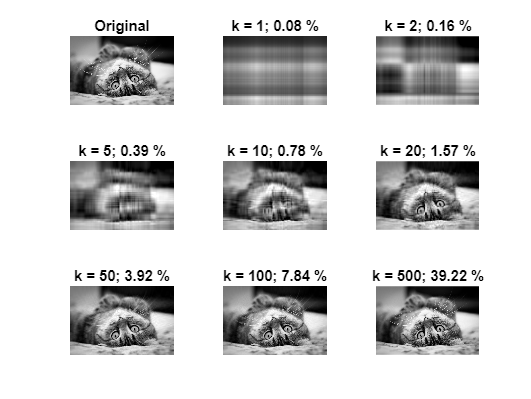

%Вывод изображений
tiledlayout(3,3)
nexttile
imshow(Im)
title('Original')

nexttile
imshow(Im_1)
title(sprintf('k = %d; %0.2f %%', 1, 100*((1275+1920)*1)/((1275+1920)*1275)))

nexttile
imshow(Im_2)
title(sprintf('k = %d; %0.2f %%', 2, 100*((1275+1920)*2)/((1275+1920)*1275)))

nexttile
imshow(Im_5)
title(sprintf('k = %d; %0.2f %%', 5, 100*((1275+1920)*5)/((1275+1920)*1275)))

nexttile
imshow(Im_10)
title(sprintf('k = %d; %0.2f %%', 10, 100*((1275+1920)*10)/((1275+1920)*1275)))

nexttile
imshow(Im_20)
title(sprintf('k = %d; %0.2f %%', 20, 100*((1275+1920)*20)/((1275+1920)*1275)))

nexttile
imshow(Im_50)
title(sprintf('k = %d; %0.2f %%', 50, 100*((1275+1920)*50)/((1275+1920)*1275)))

nexttile
imshow(Im_100)
title(sprintf('k = %d; %0.2f %%', 100, 100*((1275+1920)*100)/((1275+1920)*1275)))

nexttile
imshow(Im_500)
title(sprintf('k = %d; %0.2f %%', 500, 100*((1275+1920)*500)/((1275+1920)*1275)))